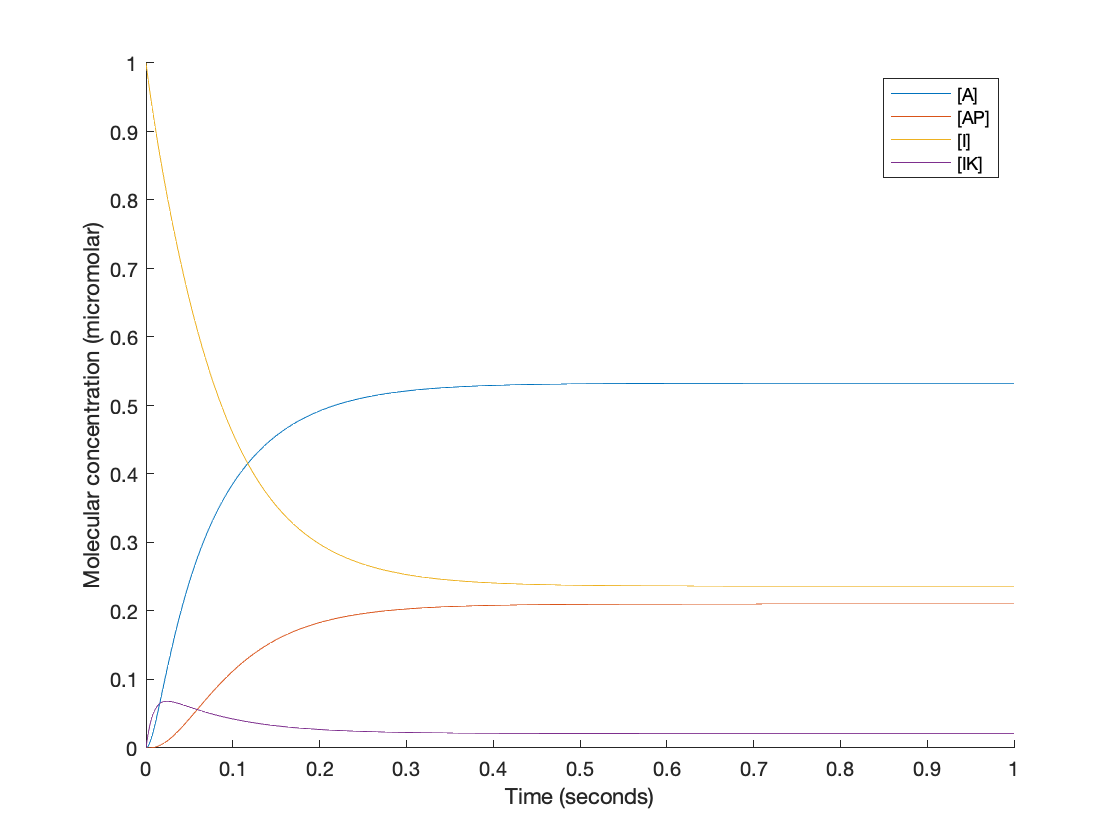

% f =@(u,w) -5*u + 6*w   +0.1; %dudt RNA rate
% g =@(u,w) -2*w + 1.2*u; %dwdt protein rate
% 
% [T, X] = ode45(@(t,x)[f(x(1),x(2));g(x(1),x(2))], [0,15], [0.0,0.14] );
% 
% figure; hold on;
% plot(T,X(:,1),'-r'); % red for RNA
% plot(T,X(:,2),'-', 'color', [0.5 0 1]); % purple for protein
% ylabel('Molecular concentration (micromolar)')
% xlabel('Time (hours)')

%rate constants, all units s^-1 except for kAon and kIon are s^-1 uM^-1
kAon = 10;
kAoff = 10;
kIon = 10;
kIoff = 10;
kIcat = 10;
kAcat = 100;

%kinase and phosphatase
Ptot = 1;
Ktot = 1;

%order of variables in each equation needs to correspond to the order of
%the d/dt equations in the ode45 equation, as well as the initial
%conditions
dAdt =@(A,AP,I,IK) -kAon*(Ptot - AP)*A + kAoff*AP + kAcat*IK;
dAPdt =@(A,AP,I,IK) kAon*(Ptot - AP)*A - kAoff*AP - kIcat*AP;
dIdt =@(A,AP,I,IK) -kIon*(Ktot - IK)*I + kIoff*IK + kIcat*AP;
dIKdt =@(A,AP,I,IK) kIon*(Ktot - IK)*I - kIoff*IK - kAcat*IK;

[T, X] = ode45(@(t,x)[dAdt(x(1),x(2),x(3),x(4));dAPdt(x(1),x(2),x(3),x(4));...
    dIdt(x(1),x(2),x(3),x(4));dIKdt(x(1),x(2),x(3),x(4))],[0,1],[0.0,0.0,1.0,0.0]);

figure; hold on;
plot(T,X(:,1));
plot(T,X(:,2));
plot(T,X(:,3));
plot(T,X(:,4));
ylabel('Molecular concentration (micromolar)')
xlabel('Time (seconds)')
legend('[A]','[AP]','[I]','[IK]');